# **Project 9**

Consider a 30-year MBS with a fixed $\textrm{WAC}$= 8% (monthly cash flows starting in January of this year). The Notional Amount of the Loan is $100,000. Use the CIR model of interest rates 


$$dr_t =\kappa \left(\overset{-}{r} -r_t \right)\mathrm{dt}+\sigma \sqrt{r_t }dW_t$$


with $r_0$ = 0.078, k = 0.6, $\overset{-}{r}$ = 0.08, $\sigma$ = 0.12. Consider the Numerix Prepayment Model in all problems  below.

**1. **

(a) Compute the price of the MBS. The code should be generic: the user is prompted for  inputs and the program runs and gives the output. 

r0=0.078; sigma=0.12; k=0.6; r_lt = 0.08;
T=30; PV0 = 100000; WAC=0.08;

rng(57)
cash_flow = Numerix_Prepayment(PV0, T, WAC, r0, k, r_lt, sigma)

cash_flow = 1.0070e+05

 (b) Compute the price of the MBS for the following ranges of the parameters: k in 0.3 to  0.9 (in increments of 0.1) and draw the graph of the price of MBS vs. k.

rng(57)
k_vec=0.3:0.1:0.9;
fast_k = (@(k_i) Numerix_Prepayment(PV0, T, WAC, r0, k_i, r_lt, sigma));
MBS_vec1 = arrayfun(@(k_i) fast_k(k_i), k_vec)

MBS_vec1 = 1.0e+05 *

    1.0098    1.0123    1.0085    1.0078    1.0051    1.0038    1.0035


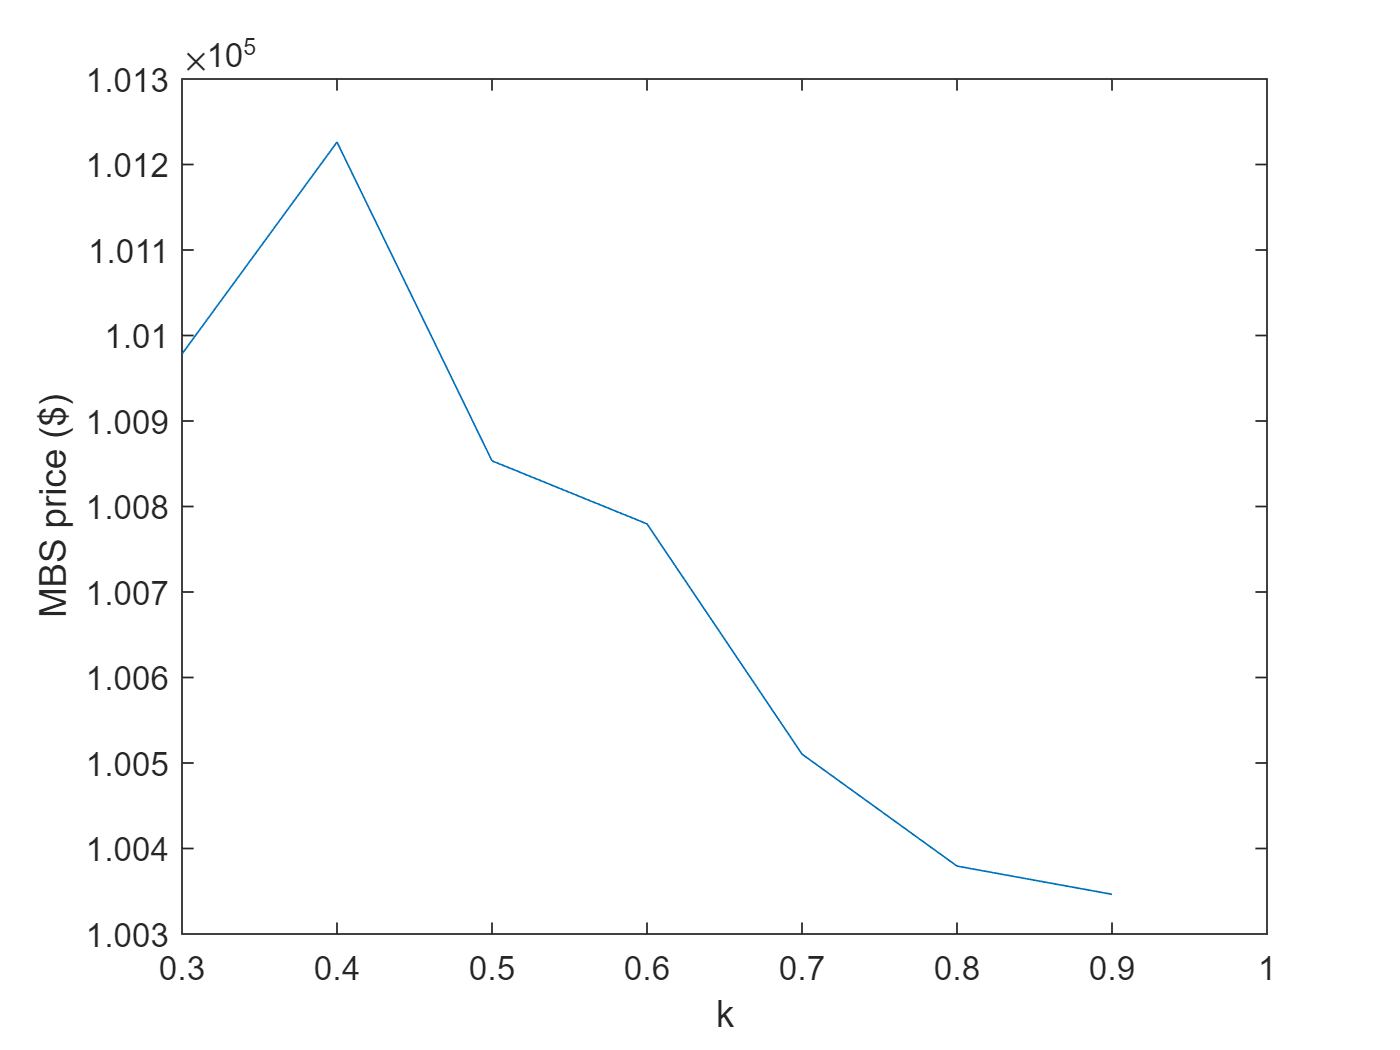

plot(k_vec, MBS_vec1)
xlabel("k")
ylabel("MBS price ($)")

(c) Compute the price of the MBS for the following ranges of the parameters: $\overset{-}{r}$ in 0.03 to  0.09 (in increments of 0.01) and draw the graph of MBS vs. $\overset{-}{r}$. 

rng(57)
r_lt_vec=0.03:0.01:0.09;
fast_r_lt = (@(r_lt_i) Numerix_Prepayment(PV0, T, WAC, r0, k, r_lt_i, sigma));
MBS_vec2 = arrayfun(@(r_lt_i) fast_r_lt(r_lt_i), r_lt_vec);
MBS_vec2 = real(MBS_vec2)

MBS_vec2 = 1.0e+05 *

    1.1142    1.0899    1.0679    1.0563    1.0537    1.0066    0.9562


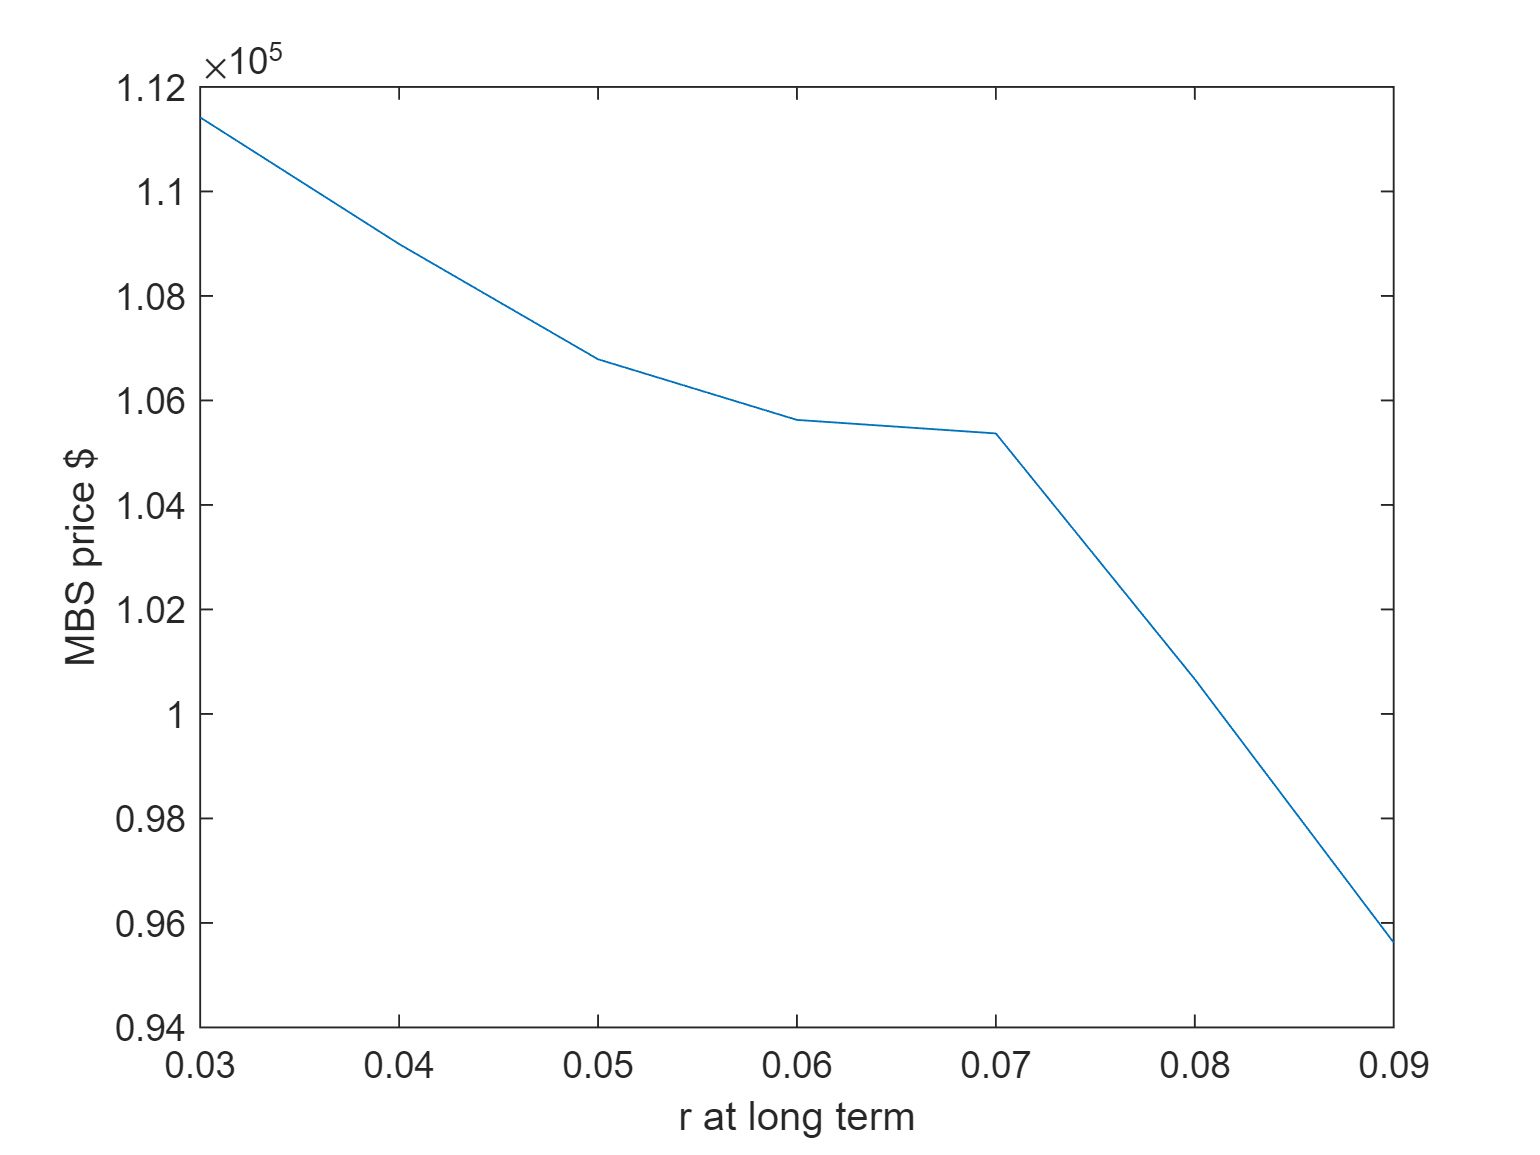

plot(r_lt_vec, MBS_vec2)
xlabel("r at long term")
ylabel("MBS price $")

**2**. Compute the Option-Adjusted-Spread (OAS) if the Market Price of MBS is $102,000. 

market_price = 102000;
r0=0.078; sigma=0.12; k=0.6; r_lt = 0.08;
T=30; dt=1/120; PV0 = 100000; WAC=0.08;

func = @(OAS_i) est_error(OAS_i, PV0, T, WAC, r0, k, r_lt, sigma, market_price);
OAS0 = -0.01;
options = optimoptions('fminunc','Algorithm','quasi-newton',"OptimalityTolerance",1e-3);
[OAS,val] = fminunc(func,OAS0,options)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


OAS = -0.0020

val = 3.0468e-06

The OAS is:

vpa(OAS,10)

$$ans = -0.001975964048$$

**3.** Compute the OAS-adjusted Duration and Convexity of the MBS, considered in the previous question.

dx=80/10000;
[P_u, P, P_d] = around_Price_OAS(OAS, PV0, T, WAC, r0, k, r_lt, sigma)

P_u = 9.6694e+04

P = 1.0200e+05

P_d = 1.0785e+05

% Duration of this OAS
durationOAS = Duration_OAS(P_u, P, P_d, dx)

durationOAS = 6.8333

% Convexity of this OAS
convexityOAS = Convexity_OAS(P_u, P, P_d, dx)

convexityOAS = 41.3849

**4.** Consider the MBS described above and the IO and PO tranches. Use the NumerixPrepayment Model and price the IO and PO tranches for: $\overset{-}{r}$ in 0.03 to 0.09 range, in increments of 0.01.

rng(57)
r_lt_vec=0.03:0.01:0.09;
fast_r_lt4 = (@(r_lt_i) Numerix_Prepayment_IOPO(PV0, T, WAC, r0, k, r_lt_i, sigma));
[IO_vec,PO_vec] = arrayfun(@(r_lt_i) fast_r_lt4(r_lt_i), r_lt_vec);
IO_vec = real(IO_vec)

IO_vec = 1.0e+04 *

    2.7202    2.6841    2.7168    3.3731    5.1242    5.3662    5.2404


PO_vec = real(PO_vec)

PO_vec = 1.0e+04 *

    8.4193    8.2260    7.9708    7.1806    5.4303    4.7156    4.3160


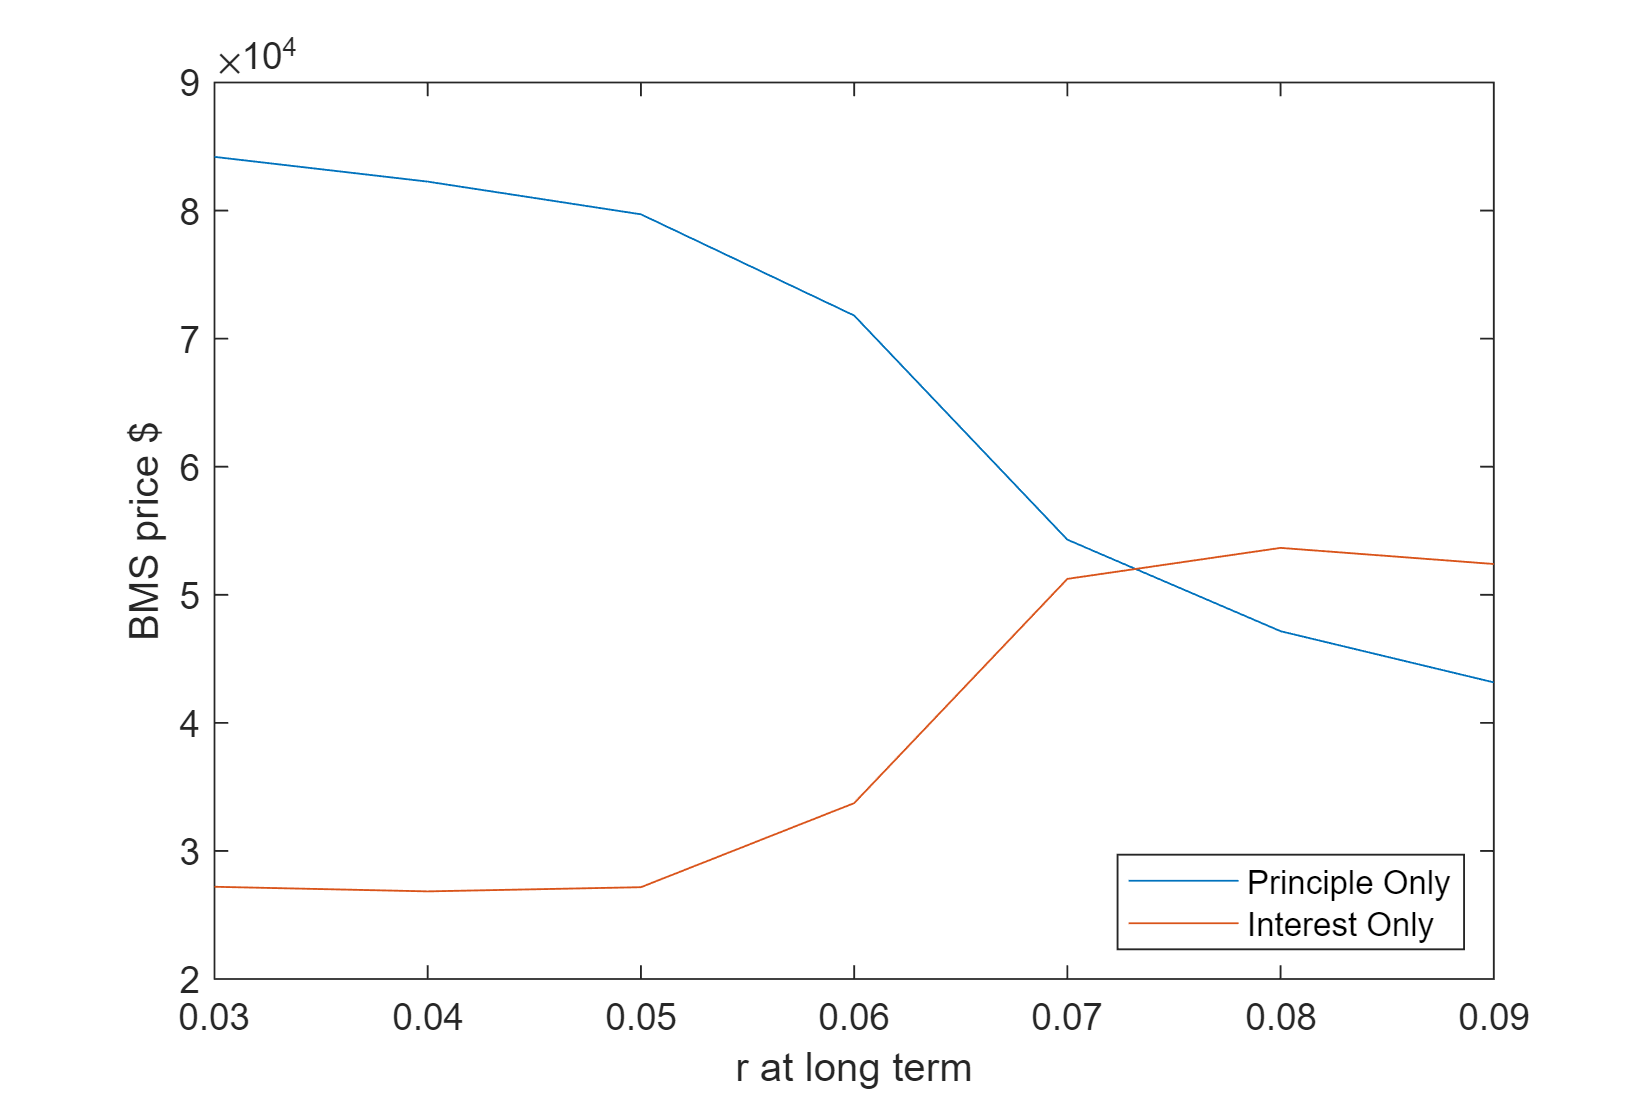

plot(r_lt_vec, PO_vec)
hold on
plot(r_lt_vec, IO_vec)
hold off
set(gcf,'Position',[400 400 600 400])
legend(["Principle Only","Interest Only"],...
    'Location','southeast','NumColumns',1)
xlabel("r at long term")
ylabel("BMS price $")

function r_mat = rate_mat_CIR(T,N,r0,sigma,k,r_lt,dt)
% CIR model
    step = T/dt;
    r_mat = zeros(step+1,N); r_mat(1,:) = r0;
    for i = 2:(step+1)
        % r_(t+1)-r_t = k(r_lt-rt)dt + sigma*sqrt(rt)*Wt
        Wt = normrnd(0,sqrt(dt),[1,N/2]);
        r_mat(i,:) = r_mat(i-1,:) + k * (r_lt-r_mat(i-1,:))*dt + sigma.*sqrt(r_mat(i-1,:)).*[Wt,-Wt];
    end
    % t_idx = [0, (1:step)*dt];
end

% Question 1
% 10 year spot rate
% function sr = ten_yr_spot_rate(rt_vec, t, T,N_path2,sigma,k,r_lt, dt)
% % r_t(T) = integral from (t) to (t+T) r_u du
%     fast_sr = (@(rt_i) mean(sum(rate_mat_CIR(T-t,N_path2,rt_i,sigma,k,r_lt,dt),1)*dt/T,2));
%     sr = arrayfun(@(rt_i) fast_sr(rt_i),rt_vec);
% end

% explicit function run faster!!!
function ten_yr_ZCB = Ten_yr_ZCB_pricing(T,t,k,sigma,r_lt,rt)
% A fucntion &  B function for CIR
    h1 = sqrt(k^2+2*sigma^2); h2 =(k+h1)/2; h3 = 2* k *r_lt/(sigma^2); 
    B_tT = (exp(h1*(T-t))-1)/(h2*(exp(h1*(T-t))-1)+h1);
    A_tT = (h1*exp(h2*(T-t))/(h2*(exp(h1*(T-t))-1)+h1))^h3;
    ten_yr_ZCB = A_tT*exp(-B_tT*rt);
end

function sr=ten_yr_spot_rate(rt_vec, t, T,sigma,k,r_lt)
% r_t(T) = integral from (t) to (t+T) r_u du
    fast_zcb = (@(rt_i) Ten_yr_ZCB_pricing(T,t,k,sigma,r_lt,rt_i));
    zcb = arrayfun(@(rt_i) fast_zcb(rt_i),rt_vec);
    sr = -log(zcb)/(T-t);
end

% Nuemrix CPR models
% Refinancing Incentive
function ri_t = Interest_Rate(R, r_10)
% RI_t = 0.28+0.14*Arctan(-8.57+430*(R-r_(t-1)(10)))
    ri_t = 0.28+0.14*atan(-8.57+430*(R-r_10));
end

% Burn Out Effect
function bu_t = Burnout(PV, PV0)
% BU_t = 0.3 + 0.7 * PV_(t-1)/PV_0
    bu_t = 0.3+0.7*(PV/PV0)';
end

% Seasonality
function sg_t = Seasonality(t)
% SG_t = min(1, t/30)
    sg_t = min(1,t/30);
end
% Seasoning
function sy_t = Seasoning(month)
    % corresponding month_vec = 1:12
    sy_vec = [0.94, 0.76, 0.74, 0.95, 0.98, 0.92, 0.98, 1.1, 1.18, 1.22, 1.23, 0.98];
    sy_t = sy_vec(month);
end

% CPR numerix model
function cpr = CPR_numerix(R, r_10, PV, PV0, t)
    cpr = Interest_Rate(R, r_10).*Burnout(PV, PV0)*Seasonality(t)*Seasoning(rem(t-1,12)+1);
end


% total payment
function c_t = total_payment_t(PV, r, N, t, CPR_t)
    MP_t = PV*r/(1-1/(1+r)^(N-(t-1)));
    PP_t = (PV-PV*r*(1/(1-(1+r)^(-N+(t-1)))-1)).*(1-(1-CPR_t).^(1/12));
    c_t = MP_t + PP_t;
end


% discount factor
function dis_fac = discount_factor(r_mat, dt, gap)
    time_step = size(r_mat,1)-1;
    N_path = size(r_mat,2);
    dis_fac = zeros(time_step/gap, N_path);
    for i = (1+gap):gap:time_step+1
        dis_fac((i-1)/gap,:) = exp(-sum(r_mat(1:i,:)*dt,1));
    end
    dis_fac = dis_fac';
end


% Numerix prepayment model
function mbs = Numerix_Prepayment(PV0, T, WAC, r0, k, r_lt, sigma)
% note T is number of years
    gap = 10;
    dt = 1/(12*gap); % divide each month by 10 <=> divide each year by 120
    r = WAC/12;
    N_month = T*12; % number of months 
    N_path = 500; % number of paths
    PV_pre =  PV0;
    Ct = zeros(N_path, N_month); % total payment

    % short rate matrix
    r_mat = rate_mat_CIR(T+10,N_path,r0,sigma,k,r_lt,dt);

    % discount factor
    dis_fac_mat = discount_factor(r_mat, dt, gap);
    for t  = 1:N_month % from 1 to N_month inclusive
        % compute the index in r_mat for month t-1
        idx_rmat = 1+10*(t-1);
        % compute 10-year rate 
        %r_10 = ten_yr_spot_rate(r_mat(idx_rmat,:),0,10,N_path2,sigma,k,r_lt,dt);
        r_10 = ten_yr_spot_rate(r_mat(idx_rmat,:),0,10,sigma,k,r_lt);
        % compute CPR
        CPRt = CPR_numerix(WAC, r_10, PV_pre, PV0, t);
        % find total payment (cash flow) at month t
        Ct(:,t) = total_payment_t(PV_pre', r, N_month, t, CPRt);
        % compute total principle payment at month t
        TTPt = Ct(:, t) - PV_pre*r;
        % update next period persent value, PVt
        PV_pre = PV_pre - TTPt;
    end

    mbs = mean(sum(dis_fac_mat(:,1:N_month).*Ct,2));
end

% Question 2
% Option Adjusted Spread (OAS) discount factor
function dis_fac = discount_factor_OAS(OAS, r_mat, dt, gap)
    time_step = size(r_mat,1)-1;
    N_path = size(r_mat,2);
    dis_fac = zeros(time_step/gap, N_path);
    for i = (1+gap):gap:time_step+1
        dis_fac((i-1)/gap,:) = exp(-sum((r_mat(1:i,:)+OAS)*dt,1));
    end
    dis_fac = dis_fac';
end

% Numerix prepayment model
function mbs = Numerix_Prepayment_OAS(OAS, PV0, T, WAC, r0, k, r_lt, sigma)
% note T is number of years
    rng(321)
    gap = 10;
    dt = 1/(12*gap); % divide each month by 10 <=> divide each year by 120
    r = WAC/12;
    N_month = T*12; % number of months 
    N_path = 2000; % number of paths
    PV_pre =  PV0;
    Ct = zeros(N_path, N_month); % total payment

    % short rate matrix
    r_mat = rate_mat_CIR(T+10,N_path,r0,sigma,k,r_lt,dt);

    % discount factor with OAS
    dis_fac_mat = discount_factor_OAS(OAS, r_mat, dt, gap);

    for t  = 1:N_month % from 1 to N_month inclusive
        % compute the index in r_mat for month t-1
        idx_rmat = 1+10*(t-1);
        % compute 10-year rate 
        %r_10 = ten_yr_spot_rate(r_mat(idx_rmat,:),0,10,N_path2,sigma,k,r_lt,dt);
        r_10 = ten_yr_spot_rate(r_mat(idx_rmat,:),0,10,sigma,k,r_lt);
        % compute CPR
        CPRt = CPR_numerix(WAC, r_10, PV_pre, PV0, t);
        % find total payment (cash flow) at month t
        Ct(:,t) = total_payment_t(PV_pre', r, N_month, t, CPRt);
        % compute total principle payment at month t
        TTPt = Ct(:, t) - PV_pre*r;
        % update next period persent value, PVt
        PV_pre = PV_pre - TTPt;
    end

    mbs = mean(sum(dis_fac_mat(:,1:N_month).*Ct,2));
end

% optimize to find OAS
function err = est_error(OAS, PV0, T, WAC, r0, k, r_lt, sigma, market_price)
    err = Numerix_Prepayment_OAS(OAS, PV0, T, WAC, r0, k, r_lt, sigma)-market_price;
    err = abs(err);
end


% Question 3
function [P_u, P, P_d] = around_Price_OAS(OAS, PV0, T, WAC, r0, k, r_lt, sigma)
    dx = 80/10000;
    P_u = Numerix_Prepayment_OAS(OAS+dx, PV0, T, WAC, r0, k, r_lt, sigma);
    P = Numerix_Prepayment_OAS(OAS, PV0, T, WAC, r0, k, r_lt, sigma);
    P_d = Numerix_Prepayment_OAS(OAS-dx, PV0, T, WAC, r0, k, r_lt, sigma);
end

function duration = Duration_OAS(P_u, P, P_d, dx)
    duration = (P_d-P_u)/(2*dx*P);
end

function convexity = Convexity_OAS(P_u, P, P_d, dx)
    convexity = (P_u+P_d-2*P)/(2*(dx^2)*P);
end


% Question 4
function [IO,PO] = Numerix_Prepayment_IOPO(PV0, T, WAC, r0, k, r_lt, sigma)
% note T is number of years
    gap = 10;
    dt = 1/(12*gap); % divide each month by 10 <=> divide each year by 120
    r = WAC/12;
    N_month = T*12; % number of months 
    N_path = 100; % number of paths
    PV_pre =  PV0;
    Interest_t = zeros(N_path, N_month); % Interest
    Principle_t = zeros(N_path, N_month); % Principle Payment

    % short rate matrix
    r_mat = rate_mat_CIR(T+10,N_path,r0,sigma,k,r_lt,dt);

    % discount factor
    dis_fac_mat = discount_factor(r_mat, dt, gap);
    for t  = 1:N_month % from 1 to N_month inclusive
        % compute the index in r_mat for month t-1
        idx_rmat = 1+10*(t-1);
        % compute 10-year rate 
        %r_10 = ten_yr_spot_rate(r_mat(idx_rmat,:),0,10,N_path2,sigma,k,r_lt,dt);
        r_10 = ten_yr_spot_rate(r_mat(idx_rmat,:),0,10,sigma,k,r_lt);
        % compute CPR
        CPRt = CPR_numerix(WAC, r_10, PV_pre, PV0, t);
        % find Interest at month t
        Interest_t(:,t) = PV_pre*r;
        % find total payment (cash flow) at month t
        Ct(:, t) = total_payment_t(PV_pre', r, N_month, t, CPRt);
        % compute total principle payment at month t
        Principle_t(:,t)  = Ct(:, t) - Interest_t(:,t);
        % update next period persent value, PVt
        PV_pre = PV_pre - Principle_t(:,t) ;
    end

    IO = mean(sum(dis_fac_mat(:,1:N_month).*Interest_t,2));
    PO = mean(sum(dis_fac_mat(:,1:N_month).*Principle_t,2));
end